the purpose of this live script is to look at an example of Rayleigh scattering in action. So far, we've looked at two simpler forms of scattering, Compton, where the photon trades some energy with the particle and bounces at a different wavelength and Thomson where photons accelerate a charged particle which then emits radiation. Where Rayleigh scattering adds to Thomson, is we're now dealing with molecules and not just atoms anymore, indices of refraction start to become important here. Rayleigh scattering applies through porous crystals. Note that Rayleigh scattering is an approximation theory. In order for it to work, the particles must be at least ten times smaller than the wavelength of the light. If this is not the case, we must resort to MIE scattering to factor in more complex features of molecules. Fortunately, Rayleigh scattering is parametrized by quite a few things, so we can make quite a few beautiful graphs here. Reference the formula for Rayleigh scattering, or open up the function attached to this lesson.

clear all
close all
%Let's start by calculating the scattering for one photon
%we will hold all variables constant here, save for the angle of the
%scattered light. Let's define some of these variables
intensity_nought=1400; %[w/m^2]
lambda=550*(10.^-9); %[m]
refractive_index=1.00029; %for air at STP
distance_from_particle=2; %distance from scatter location [m]
sphere_diameter=1*(10^-9);

scattered_intensity_one=rayleigh_scatter(intensity_nought,i,lambda,...
    refractive_index,distance_from_particle,sphere_diameter);
fprintf('The light intensity scattered from \n one particle is %d \n', scattered_intensity_one)

The light intensity scattered from 
 one particle is 5.885129e-33 


You might now intuitively  be asking why this number is so low? Well we have not factored in the number of particles doing the scattering. This will make our problem a bit more complicated. We must multiply the number of particles through the volume which this scattering is occuring, this will allow there to be much more intensity coming out the other side. 

 We will start by plotting scattering as a function of angle. Using the same input parameters from above, change them below to test different effects. 

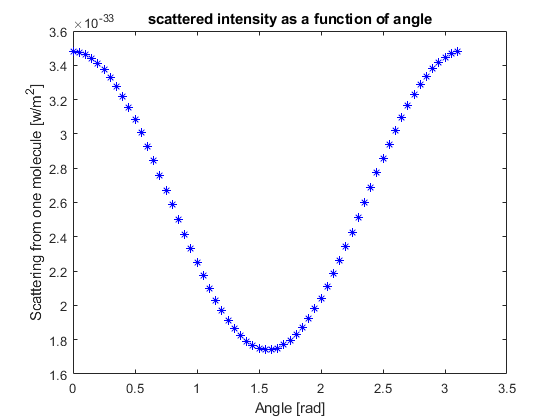

%Rayleigh Scattering intensity as a function of angle.
%we will hold all variables constant here, save for the angle of the
%scattered light. Let's define some of these variables
intensity_nought=1400; %[w/m^2]
lambda=550*(10.^-9); %[m]
refractive_index=1.00029; %for air at STP
distance_from_particle=2; %distance from scatter location [m]
sphere_diameter=1*(10^-9);

k=1;
for i=0:0.05:pi
    scattered_intensity(k)=rayleigh_scatter(intensity_nought,i,lambda,...
        refractive_index,distance_from_particle,sphere_diameter);
    angle(k)=i;
    k=k+1;
end

plot(angle,scattered_intensity,'b*')
title('scattered intensity as a function of angle')
xlabel('Angle [rad]')
ylabel('Scattering from one molecule [w/m^2]')

So what is this graph telling us? Well it's saying that there is just as much light being scattered backwards as there is forwards. It' also saying that light is scattered the least perpendicularly. Interesting. Let's move on and see the effects of both wavelength and angle. 

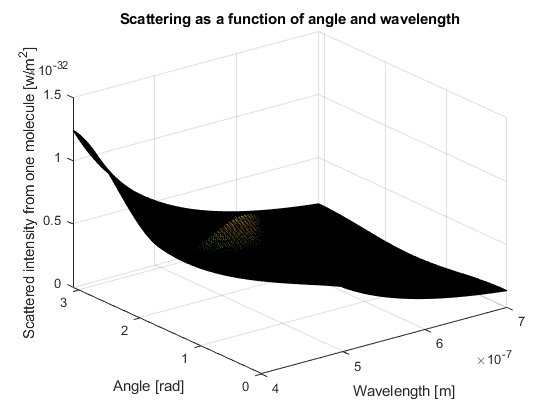

%observing the effects of angle and wavelength
intensity_nought=1400; %[w/m^2]
lambda=550*(10.^-9); %[m]
refractive_index=1.00029; %for air at STP
distance_from_particle=2; %distance from scatter location [m]
sphere_diameter=1*(10^-9);

k=1;
l=1;
for j= 400:1:700
    k=1;
    for i=0:0.05:pi
        scattered_intensity2(k,l)=rayleigh_scatter(intensity_nought,i,j*(10.^-9),...
            refractive_index,distance_from_particle,sphere_diameter);
        angle2(k)=i;
        k=k+1;
    end
    lambda_(l)=j*(10.^-9);
    l=l+1;
end

surf(lambda_,angle2,scattered_intensity2)
title('Scattering as a function of angle and wavelength')
xlabel('Wavelength [m]')
ylabel('Angle [rad]')
zlabel('Scattered intensity from one molecule [w/m^2]')

Well, open up this plot in a figure window to check out this plot more elaborately. Observe it from the heat map position x-y and then scattering as a function of variables and make sure that is makes sense to you. We can clearly see the angular term well represented here and that blue light is preferentially scattered as we expect it to be. There is the effect that makes the sky blue. 

We now want to play around with the stranger parameters here. Let's look at the effect of different refractive indices on the scattering of light through a media.

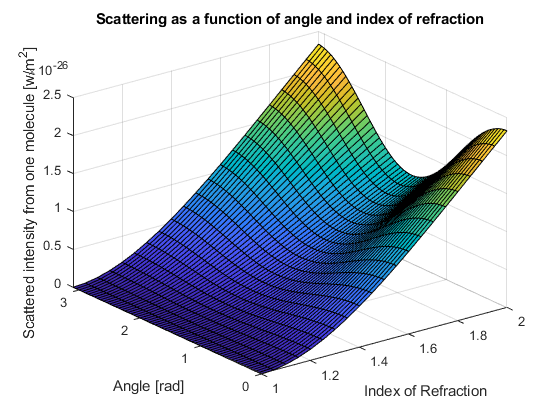

intensity_nought=1400; %[w/m^2]
lambda=550*(10.^-9); %[m]
distance_from_particle=2; %distance from scatter location [m]
sphere_diameter=1*(10^-9); %[m]

k=1;
l=1;
for j=1:.05:2
    k=1;
    for i=0:0.05:pi
        scattered_intensity3(k,l)=rayleigh_scatter(intensity_nought,i,lambda,...
            j,distance_from_particle,sphere_diameter);
        angle3(k)=i;
        k=k+1;
    end
    index_ref(l)=j;
    l=l+1;
end

surf(index_ref,angle3,scattered_intensity3) 
title('Scattering as a function of angle and index of refraction')
xlabel('Index of Refraction')
ylabel('Angle [rad]')
zlabel('Scattered intensity from one molecule [w/m^2]')

What do we notice upon flipping the graph to the x-z plane? Well, we see that as the index of refaction changes the difference between how much scattering occures stars to become much larger, as we expect with a higher index of refaction. For example with an index of refraction at 1.2 has a range of 0.1 between the highest scattered light angle and the lowest. Once we get up to index of refraction of two, the scattering range is roughly 0.7. So the various light rays spread out much more with a higher index of refraction, just as we expect them to. The last things we'll analyze for rayleigh scattering is the effect of distance and particle size. Let's make another 3-D plot and observe how this works.

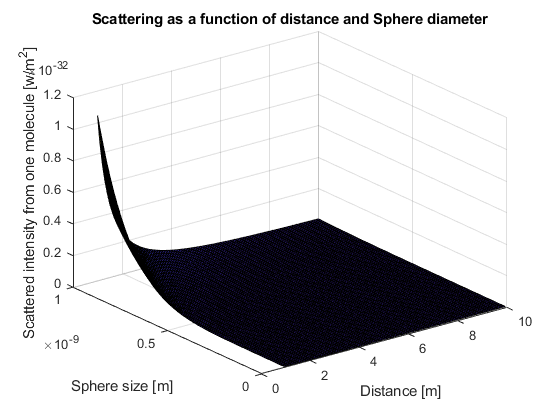

intensity_nought=1400; %[w/m^2]
lambda=550*(10.^-9); %[m]
refractive_index=1.00029;
theta=pi/4;
k=1;
l=1;
for j=1:.1:10
    k=1;
    for i=0.01:0.01:1
        scattered_intensity4(k,l)=rayleigh_scatter(intensity_nought,theta,lambda,...
            refractive_index,j,i*(10.^-9));
        sphere_diameter_(k)=i*(10.^-9);
        k=k+1;
    end
    distance(l)=j;
    l=l+1;
end

surf(distance,sphere_diameter_,scattered_intensity4) 
title('Scattering as a function of distance and Sphere diameter')
xlabel('Distance [m]')
ylabel('Sphere size [m]')
zlabel('Scattered intensity from one molecule [w/m^2]')

Once again, another beautiful 3-D plot showing us the effect of two variables acting on a third. Observe the classic inverse square being caused by the range from the particle. Flip the graph to observe scattering intensity as a function to sphere size. Observe that it's governed by the 6th power. 

Hope you enjoyed this understanding lesson. Check out more complicated models of atmospheres to see what we can do with and understanding of scattering. As per usual go back and play with the parameters to help yourself understand this content further. 